We consider a geometrically nonlinear cantilever pipe conveying fluid [1]. We set the flow velocity to be zero and then construct a 2D stable SSM around the stable straight configuration. More details about the construction can be found in [2]

[1] Paidoussis, M. P. (1998). *Fluid-structure interactions: slender structures and axial flow* (Vol. 1). Academic press. 

[2] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively. Here, both the damping and stiffness matrices are not symmetric.

clear all;
nmodes = 4;
fcload = 1;
flowspeed = 0.0;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);
lambda = sort(lambda);

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0352i
  -0.0001 - 0.0352i
  -0.0024 + 0.2203i
  -0.0024 - 0.2203i
  -0.0190 + 0.6167i
  -0.0190 - 0.6167i
  -0.0731 + 1.2068i
  -0.0731 - 1.2068i



Choose Master subspace (perform resonance analysis)

We take the first pair of modes as the master subspace and compute the corresponding 2D stable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 7;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i

sigma_out = 1182
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i

sigma_in = 1182


[W0,R0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:04
Estimated memory usage at order  2 = 2.14E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.52E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.82E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.50E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.08E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.16E-02 MB


%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 0.001971\,{\rho_{1}}^{7}+0.0008166\,{\rho_{1}}^{5}+0.001503\,{\rho_{1}}^{3}-0.006181\,\rho_{1}\\ 1.114\,{\rho_{1}}^{6}+0.7655\,{\rho_{1}}^{4}+0.05768\,{\rho_{1}}^{2}+3.516 \end{array}\right)$$

Convergence of backbone curve

syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

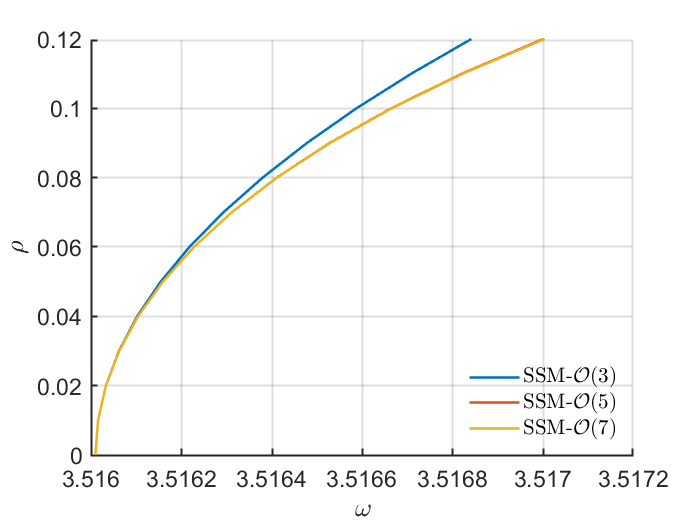

rhosamp = 0:0.01:0.12;
orders = [3 5 7];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

### Transient response prediction

We apply a static force at the free end and then release the beam to observe the free vibration of the pipe

phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
lamda(9)=26.703537555518298805445478738088174009227496691444;
lamda(10)=29.845130209102817263788730907430405063369916050237;
lamda(11)=32.986722862692838446168314183853683000367036041646;
lamda(12)=36.128315516282621834281162204648446323089539352502;
for k=1:n
   x    = 1;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   phiend(k) = phin;
end
loads = 1;
loadvector = loads.*phiend;
IC = getStaticResponse(K, M, F, loadvector);

Forward simulation with given IC

tf = 100;
nsteps = 2000;
outdof = [1 2 n+1];
redtic = tic;
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, IC);
timered = toc(redtic)

timered = 3.3527

fulltic = tic;
[tInt,zInt] = time_integration_transient(DS,0,...
    'nSteps', nsteps, 'nCycles', ceil(tf/2/pi), ...
    'integrationMethod','ode45','outdof',outdof,'init',IC);
timefull = toc(fulltic)

timefull = 43.3686

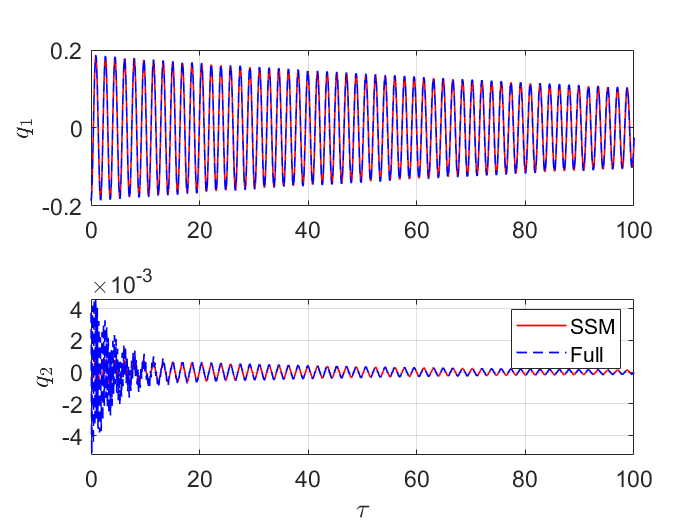


figure;
subplot(2,1,1)
plot(traj.time,traj.phy(:,1),'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1),'b--','LineWidth',1);
ylabel('$q_1$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
xlim([0,min(traj.time(end),tInt(end))]);
subplot(2,1,2)
plot(traj.time,traj.phy(:,2),'r-','LineWidth',1); hold on
plot(tInt,zInt(:,2),'b--','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$q_2$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('SSM','Full')
xlim([0,min(traj.time(end),tInt(end))]);

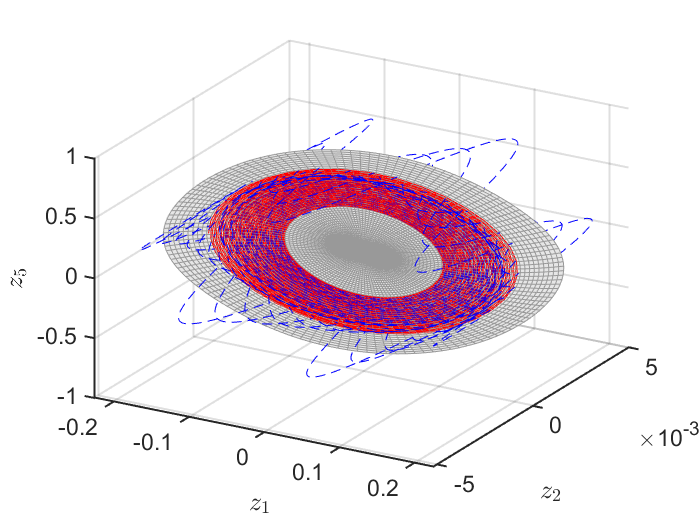


rhosamp = [0:0.01:0.5];
plotdofs = [1 2 3];
plot_2D_auto_SSM(W0,rhosamp,outdof(plotdofs));
view([30 30])
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-');
plot3(zInt(:,plotdofs(1)),zInt(:,plotdofs(2)),zInt(:,plotdofs(3)),'b--');

### Forced response - periodic orbit

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i

sigma_out = 1182
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 

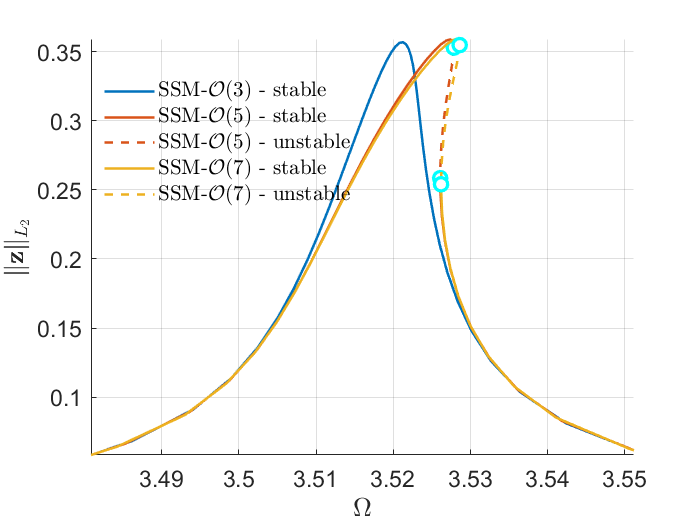

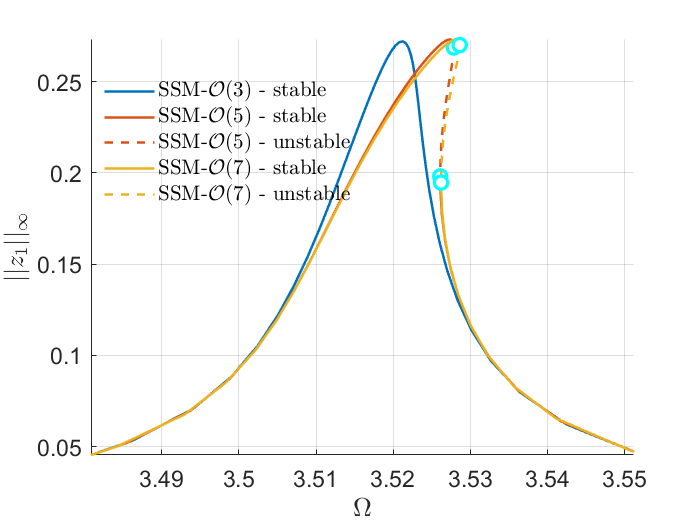

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i

sigma_out = 1182
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 

% add Forcing
kappas = [-1; 1];
coeffs = [fext fext]/2;
epsilon = 0.0006;
DS.add_forcing(coeffs, kappas, epsilon);
set(DS.Options,'BaseExcitation',true);
% set up obervables
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

% set up FRC options
freqrange = [0.99 1.01]*imag(D(1));
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.contOptions, 'PtMX', 300, 'h_max', 0.1);
set(S.FRCOptions, 'omegaSampStyle', 'cocoBD');
set(S.FRCOptions, 'outdof',obs,'method','continuation ep','p0',[]);
S.extract_FRC('freq',freqrange,[3,5,7]);

figfrc = gcf;

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 +22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i
  -0.2428 -22.0332i

sigma_out = 1182
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 + 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i
  -0.0062 - 3.5160i

sigma_in = 1182
Due to (near) outer resonance, the exisitence of t

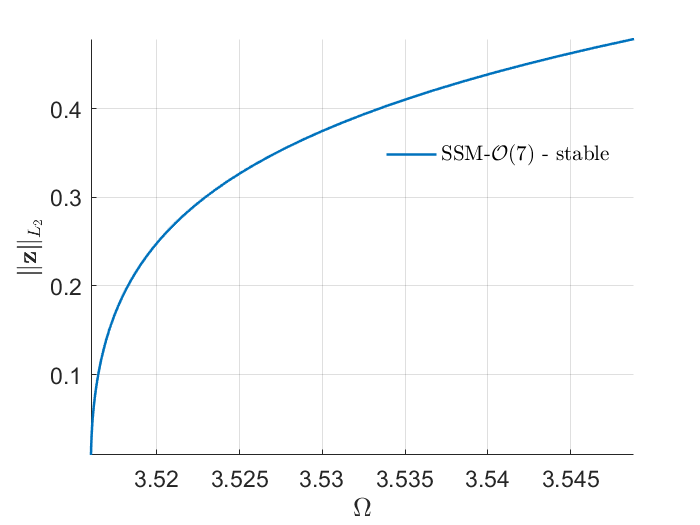

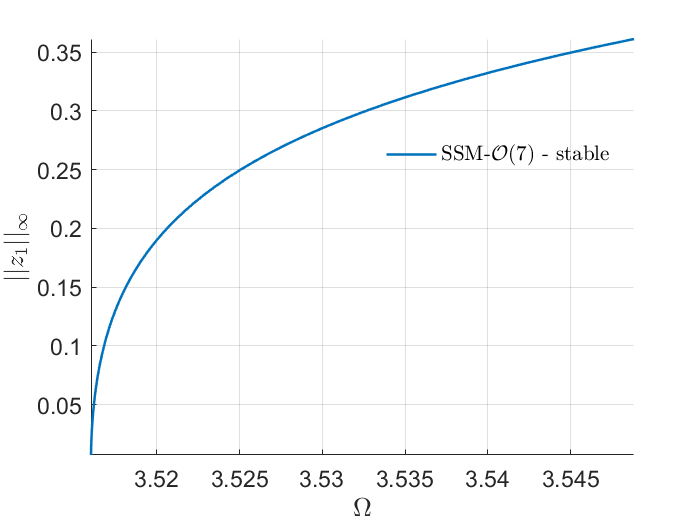

Total time spent on backbone curve computation = 00:00:01


% adding backbone curve
BB = S.extract_backbone(resonant_modes, freqrange, order);

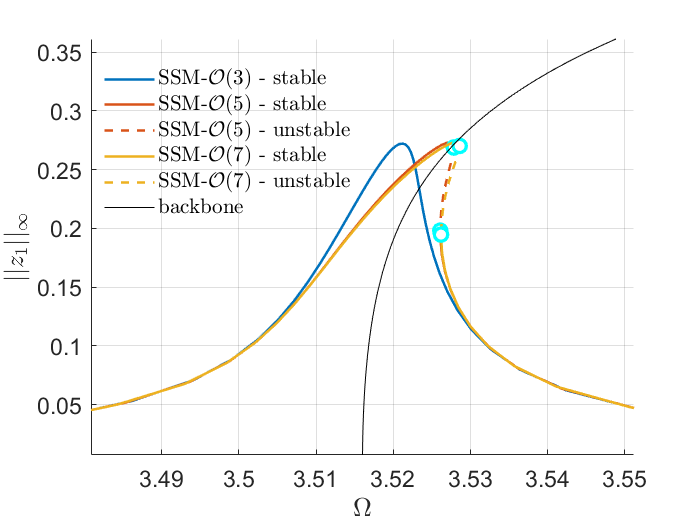

numPts = numel([BB.Omega]);
numOutdof = numel([BB.Aout])/numPts;
Aout = reshape([BB.Aout], [numOutdof, numPts]);
Aout = Aout';
figure(figfrc); hold on
plot([BB.Omega],Aout(:,1),'k-','DisplayName','backbone');

### Validation using collocation method from COCO


 Run='bd_ld_v0p01.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.55e-03  5.55e+00    0.0    0.0    0.0
   1   1  6.44e-01  3.79e-01  9.44e-04  5.55e+00    0.0    0.0    0.0
   2   1  1.00e+00  1.33e-01  7.47e-05  5.56e+00    0.0    0.1    0.0
   3   1  1.00e+00  4.88e-04  1.30e-09  5.56e+00    0.0    0.1    0.0
   4   1  1.00e+00  2.57e-08  1.49e-16  5.56e+00    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   5.5604e+00      1  EP      3.4808e+00   1.8051e+00   6.0000e-04   4.5345e-02
   10  00:00:01   5.7238e+00      2          3.5084e+00   1.7909e+00   6.0000e-04   1.4375e-01
   20  00:00:03   5.9329e+00      3          3.5180e+00   1.7860e+00   6.0000e-04   2.1958e-01
   30  00:00:04   6.0747e+00      4          3.5251e+00   1

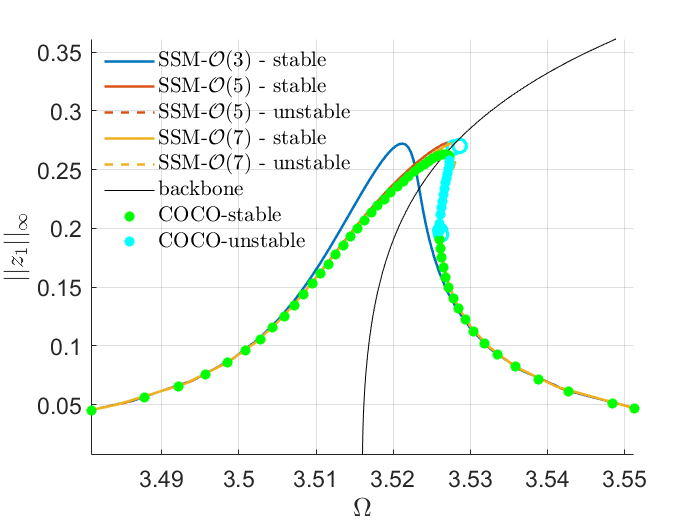

nCycles = 500;
coco = cocoWrapper(DS, nCycles, obs);
set(coco.Options, 'PtMX', 1000, 'NTST',10, 'dir_name', 'bd_ld_v0p01');
set(coco.Options, 'NAdapt', 0, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd_ld = coco.extract_FRC(freqrange);

timings.cocoFRCbd_ld = toc(start)

timings = struct with fields:
    cocoFRCbd_ld: 12.5110


#### Exercies

- Change flow speed to 0.01 and observe how the forced response curve is affected by the flow speed. You can find the discussions on the effects in [2].